%Define variables
ms=77.5;
mu=10;
ks=11000;
ku=150000;
cu=49;
%Initialise Time vector
T=linspace(0,5,10000);
x0=[0;0;0;0];
%change U value
U=zeros(10000,2);
%change U (input) to simulate a bump
H=0.08;
v=10;
L=0.8;
t_start=0.5;
t_end=t_start+L/v;
for i=1:length(T);
    t=T(i);
    if t >= t_start && t <= t_end
        xg=H/2*(1-cos((2*pi*v)/L*(t-t_start)));
        xg_dot=(pi*v*H)/L*sin((2*pi*v)/L*(t-t_start));
        U(i,1)=xg;
        U(i,2)=xg_dot;
    end 
end
%store values for later 
zeta_range = linspace(0.05, 1.5, 100);
zeta_list = zeros(1, 100);
settling_times = zeros(1, 100);
peak_accelerations_g = zeros(1, 100);
max_spring_forces = zeros(1, 100);
max_damper_forces = zeros(1, 100);        
%add zeta value and loop for solver
for idx = 1:length(zeta_range)
    zeta = zeta_range(idx);
    cs = 2 * zeta * sqrt(ks * ms);
%Define matrices
    A=[               
         0,0,1,0;
         0,0,0,1;
         -ks/ms,ks/ms,-cs/ms,cs/ms;
         ks/mu,-(ks+ku)/mu,cs/mu,-(cs+cu)/mu];
    
    B= [0,0;
         0,0;
         0,0;
         ku/mu,cu/mu];
    
    C=[
        1,-1,0,0;
        0,0,1,0];
    
    D=[0,0;
       0,0];
   
    %set up system
    sys=ss(A,B,C,D);
    %run system
    [yout,tout,xout]=lsim(sys, U, T, x0);
    %extract xs,xu,xs_dot,xu_dot
    xs=xout(:,1);
    xu=xout(:,2);
    xs_dot=xout(:,3);
    xu_dot=xout(:,4);
    % calculate forces
    F_spring= ks*(xs-xu);
    F_damper=cs*(xs_dot-xu_dot);
    %calculate max forces
    F_spring_max=max(abs(F_spring));
    F_damper_max=max(abs(F_damper));
    %peak body acceleration
    xs_dotdot=(-F_spring - F_damper)/ms;
    %settling time
    threshold=0.001; %from matlab code
    outside_threshold=find(abs(xs) > threshold);
    if ~isempty(outside_threshold);
       settling_time=tout(outside_threshold(end));
    else
       settling_time=0;
    end 
    %save values into the tracking arrays
    zeta_list(idx) = zeta;
    settling_times(idx) = settling_time;
    peak_accelerations_g(idx) = max(abs(xs_dotdot)) / 9.81;
    max_spring_forces(idx) = F_spring_max;
    max_damper_forces(idx) = F_damper_max;
end
%Multiple scenario responses
%Scenario 1: Check if both criteria can be met simultaneously (<0.3g AND <1.0s)
ideal_indices = find((peak_accelerations_g < 0.3) & (settling_times < 1.0));

%Scenario 2: Settling time balanced between 0.9s and 1.0s
balanced_indices = find((settling_times >= 0.9) & (settling_times <= 1.0));

if ~isempty(balanced_indices) 
   [~, local_min_idx] = min(peak_accelerations_g(balanced_indices));
    idx_balanced = balanced_indices(local_min_idx);
else
    [~, idx_balanced] = min(abs(settling_times - 1.0));
end

%Scenario 3: Minimum Settling Time
[~,idx_min_settling] = min(settling_times);

%Scenario 4: Minimum Acceleration
[~,idx_min_accel] = min(peak_accelerations_g);

%print the results
fprintf('OUTPUT 1: IDEAL SPECIFICATION CHECK (Comfort < 0.3g AND Settling < 1s)\n');

OUTPUT 1: IDEAL SPECIFICATION CHECK (Comfort < 0.3g AND Settling < 1s)


if ~isempty(ideal_indices)
    fprintf('Success! Ideal configuration found at Zeta: %.3f\n', zeta_list(ideal_indices(1)));
else
    fprintf('RESULT: SIMULTANEOUS TARGETS MATHEMATICALLY IMPOSSIBLE.\n');
    fprintf('The system cannot physically achieve <0.3g and settle in <1.0s simultaneously.\n');
end

RESULT: SIMULTANEOUS TARGETS MATHEMATICALLY IMPOSSIBLE.


The system cannot physically achieve <0.3g and settle in <1.0s simultaneously.



%Balanced case (Used for optimisation)
fprintf('OUTPUT 2: Balanced (Settling Time ~1.0s, Optimized Accel)\n');

OUTPUT 2: Balanced (Settling Time ~1.0s, Optimized Accel)


fprintf('Optimal Zeta:         %.3f\n', zeta_list(idx_balanced));

Optimal Zeta:         0.636


fprintf('Settling Time:        %.3f s  <-- [Target Met: 0.9s - 1.0s]\n', settling_times(idx_balanced));

Settling Time:        0.999 s  <-- [Target Met: 0.9s - 1.0s]


fprintf('Peak Acceleration:    %.3f g <-- [Minimized Compromise]\n', peak_accelerations_g(idx_balanced));

Peak Acceleration:    6.244 g <-- [Minimized Compromise]


fprintf('Max Spring Force:     %.3f N\n', max_spring_forces(idx_balanced));

Max Spring Force:     724.339 N


fprintf('Max Damper Force:     %.3f N\n', max_damper_forces(idx_balanced));

Max Damper Force:     4824.577 N



%Output 3: Minimum Settling time
fprintf('OUTPUT 3: Minimum Settling Time\n');

OUTPUT 3: Minimum Settling Time


fprintf('Optimal Zeta:         %.3f\n', zeta_list(idx_min_settling));

Optimal Zeta:         1.500


fprintf('Settling Time:        %.3f s\n', settling_times(idx_min_settling));

Settling Time:        0.734 s


fprintf('Peak Acceleration:    %.3f g\n', peak_accelerations_g(idx_min_settling));

Peak Acceleration:    10.165 g


fprintf('Max Spring Force:     %.3f N\n', max_spring_forces(idx_min_settling));

Max Spring Force:     488.346 N


fprintf('Max Damper Force:     %.3f N\n', max_damper_forces(idx_min_settling));

Max Damper Force:     7757.507 N



%Output 4: Minimum peak body acceleration
fprintf('OUTPUT 4: Minimum Peak Body Acceleration\n');

OUTPUT 4: Minimum Peak Body Acceleration


fprintf('Optimal Zeta:         %.3f\n', zeta_list(idx_min_accel));

Optimal Zeta:         0.050


fprintf('Settling Time:        %.3f s\n', settling_times(idx_min_accel));

Settling Time:        5.000 s


fprintf('Peak Acceleration:    %.3f g\n', peak_accelerations_g(idx_min_accel));

Peak Acceleration:    1.706 g


fprintf('Max Spring Force:     %.3f N\n', max_spring_forces(idx_min_accel));

Max Spring Force:     1124.799 N


fprintf('Max Damper Force:     %.3f N\n', max_damper_forces(idx_min_accel));

Max Damper Force:     644.517 N


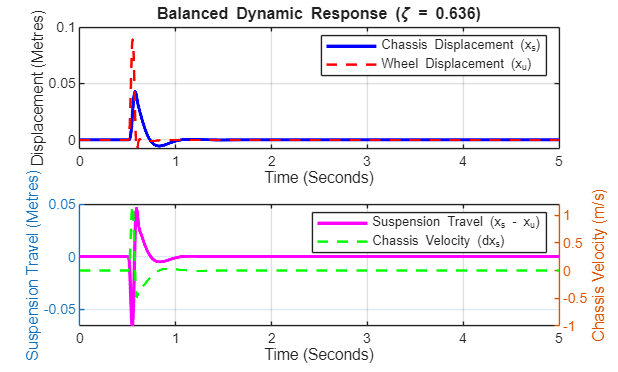


%Plotting x values, chassis displacement (xs) and wheel displacment (xu)
cs_balanced = 2 * zeta_list(idx_balanced) * sqrt(ks * ms);
A_balanced =[0, 0, 1, 0;
          0, 0, 0, 1;
          -ks/ms, ks/ms, -cs_balanced/ms, cs_balanced/ms;
          ks/mu, -(ks+ku)/mu, cs_balanced/mu, -(cs_balanced+cu)/mu];

sys_sweet = ss(A_balanced, B, C, D);
[yout, tout, xout] = lsim(sys_sweet, U, T, x0);
% Plotting x values, chassis displacement (xs) and wheel displacment (xu)
% Subplot Figure 1: Time Responses
chassis_displacement = xout(:,1);
wheel_displacement   = xout(:,2);
suspension_travel    = yout(:,1);
chassis_velocity     = yout(:,2);
figure('Name', 'Sweet Spot Dynamic Response', 'NumberTitle', 'off');
subplot(2, 1, 1);
plot(tout, chassis_displacement, 'b-', 'LineWidth', 2); hold on;
plot(tout, wheel_displacement, 'r--', 'LineWidth', 1.5);
xlabel('Time (Seconds)');
ylabel('Displacement (Metres)');
title(sprintf('Balanced Dynamic Response (\\zeta = %.3f)', zeta_list(idx_balanced)));
legend('Chassis Displacement (x_s)', 'Wheel Displacement (x_u)');
grid on;

subplot(2, 1, 2);
yyaxis left
plot(tout, suspension_travel, 'm-', 'LineWidth', 2);
ylabel('Suspension Travel (Metres)');
xlabel('Time (Seconds)');
yyaxis right
plot(tout, chassis_velocity, 'g--', 'LineWidth', 1.5);
ylabel('Chassis Velocity (m/s)');
legend('Suspension Travel (x_s - x_u)', 'Chassis Velocity (dx_s)');
grid on;

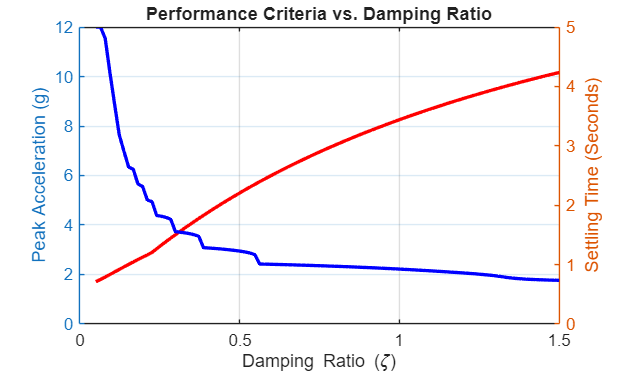


% Figure 2: Damping Sweeping Trade-off Curves
figure('Name', 'Damping Sweep Performance Trade-off', 'NumberTitle', 'off');
yyaxis left
plot(zeta_list, peak_accelerations_g, 'r-', 'LineWidth', 2);
ylabel('Peak Acceleration (g)');
xlabel('Damping Ratio (\zeta)');
grid on;

yyaxis right
plot(zeta_list, settling_times, 'b-', 'LineWidth', 2);
ylabel('Settling Time (Seconds)');
title('Performance Criteria vs. Damping Ratio');